# Load CSV Measurement Data

for k=1:1:6
    filename = sprintf('%s_%d','DD6_THETA_1',k)
    angesteuerteRichtung="theta"; %hier angeben welche Ricktung (x,y,theta) angesteurt wurde. Benoetigt, um unten automatisch cov() zu berechnen.
    
    %Zu importierende Datei auswählen
    %filename = "DD6_THETA_1_2"
    %filename = "DC8/varTheta3DC8_1";
    %Importieren und nicht relevante Informationen entfernen
    data = readtable(filename);
    data = data(6:2816,:);
    
    taskTime = 10e-3; %10ms
    

filename = 'DD6_THETA_1_1'

filename = 'DD6_THETA_1_2'

filename = 'DD6_THETA_1_3'

filename = 'DD6_THETA_1_4'

filename = 'DD6_THETA_1_5'

filename = 'DD6_THETA_1_6'

## Encoderdaten filtern

## optional: Plotten der Berechnungen

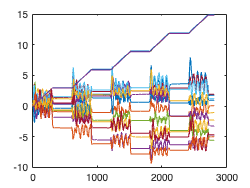

    % Plot x-Koordinatenverlauf nach Odomterie
    distX=data(:,"distX");
    distX=table2array(distX);
    plot(distX); hold on;

    
    plot(table2array(data(:,"distY")));
    plot(table2array(data(:,"distTheta")));
    %legend("distX","Odometrie xTf","Kamera x");
    %legend("distX","xOdo");
    %legend("xOdo");
    

## Umschaltpunkte ermitteln

    % In diesem Abschnitt werden die Indizes ermittelt zu denen die
    % ST-StateMachine ihren State verändert hat. In state 0 wartet der Robob 2
    % sec nach statren des task mit dem losfahren. Bei State 1 wird dann die
    % geschwindigkeit v=vsoll gesetzt und der Robo faehrt 2 sec. state 2 v=0
    % fuer 2sec. state 3 v=vsoll fuer 2 sec. state 4 v=0.
    stateOld=0;
    stateChange =zeros(11,1);
    
    for row = 1 : height(data)
        state = data{row,"state"};
        if state ~= stateOld
            stateChange(state)=row
            stateOld = state;
        end
    end

stateChange =      1
     0
     0
     0
     0
     0
     0
     0
     0
     0


stateChange =      1
   302
     0
     0
     0
     0
     0
     0
     0
     0


stateChange =      1
   302
   603
     0
     0
     0
     0
     0
     0
     0


stateChange =      1
   302
   603
   904
     0
     0
     0
     0
     0
     0


stateChange =            1
         302
         603
         904
        1205
           0
           0
           0
           0
           0


stateChange =            1
         302
         603
         904
        1205
        1506
           0
           0
           0
           0


stateChange =            1
         302
         603
         904
        1205
        1506
        1807
           0
           0
           0


stateChange =            1
         302
         603
         904
        1205
        1506
        1807
        2108
           0
           0


stateChange =            1
         302
         603
         904
        1205
        1506
        1807
        2108
        2409
           0


stateChange =            1
         302
         603
         904
        1205
        1506
        1807
        2108
        2409
        2710


stateChange =            1
         302
         603
         904
        1205
        1506
        1807
        2108
        2409
        2710


stateChange =      1
     0
     0
     0
     0
     0
     0
     0
     0
     0


stateChange =      1
   302
     0
     0
     0
     0
     0
     0
     0
     0


stateChange =      1
   302
   603
     0
     0
     0
     0
     0
     0
     0


stateChange =      1
   302
   603
   904
     0
     0
     0
     0
     0
     0


stateChange =            1
         302
         603
         904
        1205
           0
           0
           0
           0
           0


stateChange =            1
         302
         603
         904
        1205
        1506
           0
           0
           0
           0


stateChange =            1
         302
         603
         904
        1205
        1506
        1807
           0
           0
           0


stateChange =            1
         302
         603
         904
        1205
        1506
        1807
        2108
           0
           0


stateChange =            1
         302
         603
         904
        1205
        1506
        1807
        2108
        2409
           0


stateChange = 11×1
           1
         302
         603
         904
        1205
        1506
        1807
        2108
        2409
        2710


stateChange = 11×1
           1
         302
         603
         904
        1205
        1506
        1807
        2108
        2409
        2710


stateChange = 11×1
     1
     0
     0
     0
     0
     0
     0
     0
     0
     0


stateChange = 11×1
     1
   302
     0
     0
     0
     0
     0
     0
     0
     0


stateChange = 11×1
     1
   302
   603
     0
     0
     0
     0
     0
     0
     0


stateChange = 11×1
     1
   302
   603
   904
     0
     0
     0
     0
     0
     0


stateChange = 11×1
           1
         302
         603
         904
        1205
           0
           0
           0
           0
           0


stateChange = 11×1
           1
         302
         603
         904
        1205
        1506
           0
           0
           0
           0


stateChange = 11×1
           1
         302
         603
         904
        1205
        1506
        1807
           0
           0
           0


stateChange = 11×1
           1
         302
         603
         904
        1205
        1506
        1807
        2108
           0
           0


stateChange = 11×1
           1
         302
         603
         904
        1205
        1506
        1807
        2108
        2409
           0


stateChange = 11×1
           1
         302
         603
         904
        1205
        1506
        1807
        2108
        2409
        2710


stateChange = 11×1
           1
         302
         603
         904
        1205
        1506
        1807
        2108
        2409
        2710


stateChange = 11×1
     1
     0
     0
     0
     0
     0
     0
     0
     0
     0


stateChange = 11×1
     1
   302
     0
     0
     0
     0
     0
     0
     0
     0


stateChange = 11×1
     1
   302
   603
     0
     0
     0
     0
     0
     0
     0


stateChange = 11×1
     1
   302
   603
   904
     0
     0
     0
     0
     0
     0


stateChange = 11×1
           1
         302
         603
         904
        1205
           0
           0
           0
           0
           0


stateChange = 11×1
           1
         302
         603
         904
        1205
        1506
           0
           0
           0
           0


stateChange = 11×1
           1
         302
         603
         904
        1205
        1506
        1807
           0
           0
           0


stateChange = 11×1
           1
         302
         603
         904
        1205
        1506
        1807
        2108
           0
           0


stateChange = 11×1
           1
         302
         603
         904
        1205
        1506
        1807
        2108
        2409
           0


stateChange = 11×1
           1
         302
         603
         904
        1205
        1506
        1807
        2108
        2409
        2710


stateChange = 11×1
           1
         302
         603
         904
        1205
        1506
        1807
        2108
        2409
        2710


stateChange = 11×1
     1
     0
     0
     0
     0
     0
     0
     0
     0
     0


stateChange = 11×1
     1
   302
     0
     0
     0
     0
     0
     0
     0
     0


stateChange = 11×1
     1
   302
   603
     0
     0
     0
     0
     0
     0
     0


stateChange = 11×1
     1
   302
   603
   904
     0
     0
     0
     0
     0
     0


stateChange = 11×1
           1
         302
         603
         904
        1205
           0
           0
           0
           0
           0


stateChange = 11×1
           1
         302
         603
         904
        1205
        1506
           0
           0
           0
           0


stateChange = 11×1
           1
         302
         603
         904
        1205
        1506
        1807
           0
           0
           0


stateChange = 11×1
           1
         302
         603
         904
        1205
        1506
        1807
        2108
           0
           0


stateChange = 11×1
           1
         302
         603
         904
        1205
        1506
        1807
        2108
        2409
           0


stateChange = 11×1
           1
         302
         603
         904
        1205
        1506
        1807
        2108
        2409
        2710


stateChange = 11×1
           1
         302
         603
         904
        1205
        1506
        1807
        2108
        2409
        2710


stateChange = 11×1
     1
     0
     0
     0
     0
     0
     0
     0
     0
     0


stateChange = 11×1
     1
   302
     0
     0
     0
     0
     0
     0
     0
     0


stateChange = 11×1
     1
   302
   603
     0
     0
     0
     0
     0
     0
     0


stateChange = 11×1
     1
   302
   603
   904
     0
     0
     0
     0
     0
     0


stateChange = 11×1
           1
         302
         603
         904
        1205
           0
           0
           0
           0
           0


stateChange = 11×1
           1
         302
         603
         904
        1205
        1506
           0
           0
           0
           0


stateChange = 11×1
           1
         302
         603
         904
        1205
        1506
        1807
           0
           0
           0


stateChange = 11×1
           1
         302
         603
         904
        1205
        1506
        1807
        2108
           0
           0


stateChange = 11×1
           1
         302
         603
         904
        1205
        1506
        1807
        2108
        2409
           0


stateChange = 11×1
           1
         302
         603
         904
        1205
        1506
        1807
        2108
        2409
        2710


stateChange = 11×1
           1
         302
         603
         904
        1205
        1506
        1807
        2108
        2409
        2710


## Berechnen der zurueckgelegten Strecken je Ansteuerung

    % In diesem Abschnitt wird anhand der zuvor berechneten Odometrie ermittelt
    % welche Strecke der Robo zurueckgelegt hat und welche er haette
    % zurücklegen sollen
    xDiffIntervall = zeros(5,1);
    yDiffIntervall = zeros(5,1);
    thetaDiffIntervall =zeros(5,1);
    
    xDiffIntervall(1) = data{stateChange(2), "distX"}

xDiffIntervall =     0.5845
         0
         0
         0
         0


xDiffIntervall = 5×1
   -1.1026
         0
         0
         0
         0


xDiffIntervall = 5×1
    1.7580
         0
         0
         0
         0


xDiffIntervall = 5×1
    0.7041
         0
         0
         0
         0


xDiffIntervall = 5×1
    1.3683
         0
         0
         0
         0


xDiffIntervall = 5×1
   -1.0185
         0
         0
         0
         0


    yDiffIntervall(1) = data{stateChange(2), "distY"}

yDiffIntervall =     0.5931
         0
         0
         0
         0


yDiffIntervall = 5×1
    0.0486
         0
         0
         0
         0


yDiffIntervall = 5×1
   -0.1150
         0
         0
         0
         0


yDiffIntervall = 5×1
    1.3013
         0
         0
         0
         0


yDiffIntervall = 5×1
    1.6848
         0
         0
         0
         0


yDiffIntervall = 5×1
    1.0942
         0
         0
         0
         0


    thetaDiffIntervall(1) = data{stateChange(2),"distTheta"}

thetaDiffIntervall =     2.8952
         0
         0
         0
         0


thetaDiffIntervall = 5×1
    2.8886
         0
         0
         0
         0


thetaDiffIntervall = 5×1
    2.8981
         0
         0
         0
         0


thetaDiffIntervall = 5×1
    2.8853
         0
         0
         0
         0


thetaDiffIntervall = 5×1
    2.8966
         0
         0
         0
         0


thetaDiffIntervall = 5×1
    2.8922
         0
         0
         0
         0


    
    for i=2 : length(stateChange)-1
        xDiffIntervall(i) = data{stateChange(i+1), "distX"} - data{stateChange(i), "distX"}
        yDiffIntervall(i) = data{stateChange(i+1), "distY"} - data{stateChange(i), "distY"}
        thetaDiffIntervall(i) = data{stateChange(i+1), "distTheta"} - data{stateChange(i), "distTheta"}
    end

xDiffIntervall =     0.5845
   -0.2790
         0
         0
         0


yDiffIntervall =     0.5931
   -1.4956
         0
         0
         0


thetaDiffIntervall =     2.8952
    0.0672
         0
         0
         0


xDiffIntervall =     0.5845
   -0.2790
    1.4126
         0
         0


yDiffIntervall =     0.5931
   -1.4956
   -0.2736
         0
         0


thetaDiffIntervall =     2.8952
    0.0672
    2.9021
         0
         0


xDiffIntervall =     0.5845
   -0.2790
    1.4126
    0.2126
         0


yDiffIntervall =     0.5931
   -1.4956
   -0.2736
    0.1483
         0


thetaDiffIntervall =     2.8952
    0.0672
    2.9021
    0.0775
         0


xDiffIntervall =     0.5845
   -0.2790
    1.4126
    0.2126
    0.6288


yDiffIntervall =     0.5931
   -1.4956
   -0.2736
    0.1483
    1.6772


thetaDiffIntervall =     2.8952
    0.0672
    2.9021
    0.0775
    2.8874


xDiffIntervall =     0.5845
   -0.2790
    1.4126
    0.2126
    0.6288
    0.4340


yDiffIntervall =     0.5931
   -1.4956
   -0.2736
    0.1483
    1.6772
   -1.4931


thetaDiffIntervall =     2.8952
    0.0672
    2.9021
    0.0775
    2.8874
    0.0843


xDiffIntervall =     0.5845
   -0.2790
    1.4126
    0.2126
    0.6288
    0.4340
   -0.3587


yDiffIntervall =     0.5931
   -1.4956
   -0.2736
    0.1483
    1.6772
   -1.4931
    0.9690


thetaDiffIntervall =     2.8952
    0.0672
    2.9021
    0.0775
    2.8874
    0.0843
    2.8921


xDiffIntervall =     0.5845
   -0.2790
    1.4126
    0.2126
    0.6288
    0.4340
   -0.3587
    0.9963


yDiffIntervall =     0.5931
   -1.4956
   -0.2736
    0.1483
    1.6772
   -1.4931
    0.9690
   -1.8331


thetaDiffIntervall =     2.8952
    0.0672
    2.9021
    0.0775
    2.8874
    0.0843
    2.8921
    0.0694


xDiffIntervall =     0.5845
   -0.2790
    1.4126
    0.2126
    0.6288
    0.4340
   -0.3587
    0.9963
   -0.1683


yDiffIntervall =     0.5931
   -1.4956
   -0.2736
    0.1483
    1.6772
   -1.4931
    0.9690
   -1.8331
    0.9511


thetaDiffIntervall =     2.8952
    0.0672
    2.9021
    0.0775
    2.8874
    0.0843
    2.8921
    0.0694
    2.8946


xDiffIntervall =     0.5845
   -0.2790
    1.4126
    0.2126
    0.6288
    0.4340
   -0.3587
    0.9963
   -0.1683
   -1.6960


yDiffIntervall =     0.5931
   -1.4956
   -0.2736
    0.1483
    1.6772
   -1.4931
    0.9690
   -1.8331
    0.9511
    0.8207


thetaDiffIntervall =     2.8952
    0.0672
    2.9021
    0.0775
    2.8874
    0.0843
    2.8921
    0.0694
    2.8946
    0.0594


xDiffIntervall = 5×1
   -1.1026
   -0.7129
         0
         0
         0


yDiffIntervall = 5×1
    0.0486
   -0.7542
         0
         0
         0


thetaDiffIntervall = 5×1
    2.8886
    0.0619
         0
         0
         0


xDiffIntervall = 5×1
   -1.1026
   -0.7129
    0.0841
         0
         0


yDiffIntervall = 5×1
    0.0486
   -0.7542
   -1.2553
         0
         0


thetaDiffIntervall = 5×1
    2.8886
    0.0619
    2.8941
         0
         0


xDiffIntervall = 5×1
   -1.1026
   -0.7129
    0.0841
   -3.7950
         0


yDiffIntervall = 5×1
    0.0486
   -0.7542
   -1.2553
   -0.3503
         0


thetaDiffIntervall = 5×1
    2.8886
    0.0619
    2.8941
    0.0551
         0


xDiffIntervall = 5×1
   -1.1026
   -0.7129
    0.0841
   -3.7950
    0.7484


yDiffIntervall = 5×1
    0.0486
   -0.7542
   -1.2553
   -0.3503
    0.6264


thetaDiffIntervall = 5×1
    2.8886
    0.0619
    2.8941
    0.0551
    2.8937


xDiffIntervall = 6×1
   -1.1026
   -0.7129
    0.0841
   -3.7950
    0.7484
   -2.1123


yDiffIntervall = 6×1
    0.0486
   -0.7542
   -1.2553
   -0.3503
    0.6264
   -0.6519


thetaDiffIntervall = 6×1
    2.8886
    0.0619
    2.8941
    0.0551
    2.8937
    0.0683


xDiffIntervall = 7×1
   -1.1026
   -0.7129
    0.0841
   -3.7950
    0.7484
   -2.1123
    1.3727


yDiffIntervall = 7×1
    0.0486
   -0.7542
   -1.2553
   -0.3503
    0.6264
   -0.6519
    0.7772


thetaDiffIntervall = 7×1
    2.8886
    0.0619
    2.8941
    0.0551
    2.8937
    0.0683
    2.9018


xDiffIntervall = 8×1
   -1.1026
   -0.7129
    0.0841
   -3.7950
    0.7484
   -2.1123
    1.3727
   -0.7661


yDiffIntervall = 8×1
    0.0486
   -0.7542
   -1.2553
   -0.3503
    0.6264
   -0.6519
    0.7772
   -2.4058


thetaDiffIntervall = 8×1
    2.8886
    0.0619
    2.8941
    0.0551
    2.8937
    0.0683
    2.9018
    0.0685


xDiffIntervall = 9×1
   -1.1026
   -0.7129
    0.0841
   -3.7950
    0.7484
   -2.1123
    1.3727
   -0.7661
    0.6687


yDiffIntervall = 9×1
    0.0486
   -0.7542
   -1.2553
   -0.3503
    0.6264
   -0.6519
    0.7772
   -2.4058
    0.0026


thetaDiffIntervall = 9×1
    2.8886
    0.0619
    2.8941
    0.0551
    2.8937
    0.0683
    2.9018
    0.0685
    2.9034


xDiffIntervall = 10×1
   -1.1026
   -0.7129
    0.0841
   -3.7950
    0.7484
   -2.1123
    1.3727
   -0.7661
    0.6687
    0.9122


yDiffIntervall = 10×1
    0.0486
   -0.7542
   -1.2553
   -0.3503
    0.6264
   -0.6519
    0.7772
   -2.4058
    0.0026
   -1.5800


thetaDiffIntervall = 10×1
    2.8886
    0.0619
    2.8941
    0.0551
    2.8937
    0.0683
    2.9018
    0.0685
    2.9034
    0.0842


xDiffIntervall = 5×1
    1.7580
   -0.3321
         0
         0
         0


yDiffIntervall = 5×1
   -0.1150
   -0.2173
         0
         0
         0


thetaDiffIntervall = 5×1
    2.8981
    0.0865
         0
         0
         0


xDiffIntervall = 5×1
    1.7580
   -0.3321
    0.5934
         0
         0


yDiffIntervall = 5×1
   -0.1150
   -0.2173
    2.3265
         0
         0


thetaDiffIntervall = 5×1
    2.8981
    0.0865
    2.8916
         0
         0


xDiffIntervall = 5×1
    1.7580
   -0.3321
    0.5934
    0.3631
         0


yDiffIntervall = 5×1
   -0.1150
   -0.2173
    2.3265
   -0.6698
         0


thetaDiffIntervall = 5×1
    2.8981
    0.0865
    2.8916
    0.0897
         0


xDiffIntervall = 5×1
    1.7580
   -0.3321
    0.5934
    0.3631
   -0.3985


yDiffIntervall = 5×1
   -0.1150
   -0.2173
    2.3265
   -0.6698
    0.3937


thetaDiffIntervall = 5×1
    2.8981
    0.0865
    2.8916
    0.0897
    2.9056


xDiffIntervall = 6×1
    1.7580
   -0.3321
    0.5934
    0.3631
   -0.3985
    0.4827


yDiffIntervall = 6×1
   -0.1150
   -0.2173
    2.3265
   -0.6698
    0.3937
   -1.0968


thetaDiffIntervall = 6×1
    2.8981
    0.0865
    2.8916
    0.0897
    2.9056
    0.0752


xDiffIntervall = 7×1
    1.7580
   -0.3321
    0.5934
    0.3631
   -0.3985
    0.4827
   -0.4251


yDiffIntervall = 7×1
   -0.1150
   -0.2173
    2.3265
   -0.6698
    0.3937
   -1.0968
    1.7334


thetaDiffIntervall = 7×1
    2.8981
    0.0865
    2.8916
    0.0897
    2.9056
    0.0752
    2.9031


xDiffIntervall = 8×1
    1.7580
   -0.3321
    0.5934
    0.3631
   -0.3985
    0.4827
   -0.4251
    0.9122


yDiffIntervall = 8×1
   -0.1150
   -0.2173
    2.3265
   -0.6698
    0.3937
   -1.0968
    1.7334
   -1.8663


thetaDiffIntervall = 8×1
    2.8981
    0.0865
    2.8916
    0.0897
    2.9056
    0.0752
    2.9031
    0.0662


xDiffIntervall = 9×1
    1.7580
   -0.3321
    0.5934
    0.3631
   -0.3985
    0.4827
   -0.4251
    0.9122
   -0.6509


yDiffIntervall = 9×1
   -0.1150
   -0.2173
    2.3265
   -0.6698
    0.3937
   -1.0968
    1.7334
   -1.8663
    0.2684


thetaDiffIntervall = 9×1
    2.8981
    0.0865
    2.8916
    0.0897
    2.9056
    0.0752
    2.9031
    0.0662
    2.8945


xDiffIntervall = 10×1
    1.7580
   -0.3321
    0.5934
    0.3631
   -0.3985
    0.4827
   -0.4251
    0.9122
   -0.6509
   -0.3631


yDiffIntervall = 10×1
   -0.1150
   -0.2173
    2.3265
   -0.6698
    0.3937
   -1.0968
    1.7334
   -1.8663
    0.2684
    0.2148


thetaDiffIntervall = 10×1
    2.8981
    0.0865
    2.8916
    0.0897
    2.9056
    0.0752
    2.9031
    0.0662
    2.8945
    0.0739


xDiffIntervall = 5×1
    0.7041
   -1.3462
         0
         0
         0


yDiffIntervall = 5×1
    1.3013
   -0.9766
         0
         0
         0


thetaDiffIntervall = 5×1
    2.8853
    0.0626
         0
         0
         0


xDiffIntervall = 5×1
    0.7041
   -1.3462
    0.1550
         0
         0


yDiffIntervall = 5×1
    1.3013
   -0.9766
    0.6468
         0
         0


thetaDiffIntervall = 5×1
    2.8853
    0.0626
    2.8909
         0
         0


xDiffIntervall = 5×1
    0.7041
   -1.3462
    0.1550
   -2.0503
         0


yDiffIntervall = 5×1
    1.3013
   -0.9766
    0.6468
    0.6724
         0


thetaDiffIntervall = 5×1
    2.8853
    0.0626
    2.8909
    0.0597
         0


xDiffIntervall = 5×1
    0.7041
   -1.3462
    0.1550
   -2.0503
    0.7838


yDiffIntervall = 5×1
    1.3013
   -0.9766
    0.6468
    0.6724
    1.2911


thetaDiffIntervall = 5×1
    2.8853
    0.0626
    2.8909
    0.0597
    2.8891


xDiffIntervall = 6×1
    0.7041
   -1.3462
    0.1550
   -2.0503
    0.7838
   -3.3035


yDiffIntervall = 6×1
    1.3013
   -0.9766
    0.6468
    0.6724
    1.2911
   -1.0073


thetaDiffIntervall = 6×1
    2.8853
    0.0626
    2.8909
    0.0597
    2.8891
    0.0726


xDiffIntervall = 7×1
    0.7041
   -1.3462
    0.1550
   -2.0503
    0.7838
   -3.3035
    1.4746


yDiffIntervall = 7×1
    1.3013
   -0.9766
    0.6468
    0.6724
    1.2911
   -1.0073
   -0.9690


thetaDiffIntervall = 7×1
    2.8853
    0.0626
    2.8909
    0.0597
    2.8891
    0.0726
    2.8958


xDiffIntervall = 8×1
    0.7041
   -1.3462
    0.1550
   -2.0503
    0.7838
   -3.3035
    1.4746
   -0.6067


yDiffIntervall = 8×1
    1.3013
   -0.9766
    0.6468
    0.6724
    1.2911
   -1.0073
   -0.9690
   -2.5643


thetaDiffIntervall = 8×1
    2.8853
    0.0626
    2.8909
    0.0597
    2.8891
    0.0726
    2.8958
    0.0676


xDiffIntervall = 9×1
    0.7041
   -1.3462
    0.1550
   -2.0503
    0.7838
   -3.3035
    1.4746
   -0.6067
    1.3816


yDiffIntervall = 9×1
    1.3013
   -0.9766
    0.6468
    0.6724
    1.2911
   -1.0073
   -0.9690
   -2.5643
   -0.3630


thetaDiffIntervall = 9×1
    2.8853
    0.0626
    2.8909
    0.0597
    2.8891
    0.0726
    2.8958
    0.0676
    2.8968


xDiffIntervall = 10×1
    0.7041
   -1.3462
    0.1550
   -2.0503
    0.7838
   -3.3035
    1.4746
   -0.6067
    1.3816
    0.5491


yDiffIntervall = 10×1
    1.3013
   -0.9766
    0.6468
    0.6724
    1.2911
   -1.0073
   -0.9690
   -2.5643
   -0.3630
   -1.2681


thetaDiffIntervall = 10×1
    2.8853
    0.0626
    2.8909
    0.0597
    2.8891
    0.0726
    2.8958
    0.0676
    2.8968
    0.0844


xDiffIntervall = 5×1
    1.3683
    0.1506
         0
         0
         0


yDiffIntervall = 5×1
    1.6848
   -1.1965
         0
         0
         0


thetaDiffIntervall = 5×1
    2.8966
    0.0915
         0
         0
         0


xDiffIntervall = 5×1
    1.3683
    0.1506
    1.1292
         0
         0


yDiffIntervall = 5×1
    1.6848
   -1.1965
   -2.7075
         0
         0


thetaDiffIntervall = 5×1
    2.8966
    0.0915
    2.9042
         0
         0


xDiffIntervall = 5×1
    1.3683
    0.1506
    1.1292
   -0.0133
         0


yDiffIntervall = 5×1
    1.6848
   -1.1965
   -2.7075
   -1.3269
         0


thetaDiffIntervall = 5×1
    2.8966
    0.0915
    2.9042
    0.0895
         0


xDiffIntervall = 5×1
    1.3683
    0.1506
    1.1292
   -0.0133
   -0.6067


yDiffIntervall = 5×1
    1.6848
   -1.1965
   -2.7075
   -1.3269
    1.0917


thetaDiffIntervall = 5×1
    2.8966
    0.0915
    2.9042
    0.0895
    2.8991


xDiffIntervall = 6×1
    1.3683
    0.1506
    1.1292
   -0.0133
   -0.6067
    0.9565


yDiffIntervall = 6×1
    1.6848
   -1.1965
   -2.7075
   -1.3269
    1.0917
   -1.9737


thetaDiffIntervall = 6×1
    2.8966
    0.0915
    2.9042
    0.0895
    2.8991
    0.0746


xDiffIntervall = 7×1
    1.3683
    0.1506
    1.1292
   -0.0133
   -0.6067
    0.9565
   -0.3587


yDiffIntervall = 7×1
    1.6848
   -1.1965
   -2.7075
   -1.3269
    1.0917
   -1.9737
    0.2736


thetaDiffIntervall = 7×1
    2.8966
    0.0915
    2.9042
    0.0895
    2.8991
    0.0746
    2.8931


xDiffIntervall = 8×1
    1.3683
    0.1506
    1.1292
   -0.0133
   -0.6067
    0.9565
   -0.3587
    0.1151


yDiffIntervall = 8×1
    1.6848
   -1.1965
   -2.7075
   -1.3269
    1.0917
   -1.9737
    0.2736
   -0.8948


thetaDiffIntervall = 8×1
    2.8966
    0.0915
    2.9042
    0.0895
    2.8991
    0.0746
    2.8931
    0.0682


xDiffIntervall = 9×1
    1.3683
    0.1506
    1.1292
   -0.0133
   -0.6067
    0.9565
   -0.3587
    0.1151
   -0.6377


yDiffIntervall = 9×1
    1.6848
   -1.1965
   -2.7075
   -1.3269
    1.0917
   -1.9737
    0.2736
   -0.8948
    0.4244


thetaDiffIntervall = 9×1
    2.8966
    0.0915
    2.9042
    0.0895
    2.8991
    0.0746
    2.8931
    0.0682
    2.8947


xDiffIntervall = 10×1
    1.3683
    0.1506
    1.1292
   -0.0133
   -0.6067
    0.9565
   -0.3587
    0.1151
   -0.6377
   -0.9078


yDiffIntervall = 10×1
    1.6848
   -1.1965
   -2.7075
   -1.3269
    1.0917
   -1.9737
    0.2736
   -0.8948
    0.4244
   -0.0332


thetaDiffIntervall = 10×1
    2.8966
    0.0915
    2.9042
    0.0895
    2.8991
    0.0746
    2.8931
    0.0682
    2.8947
    0.0743


xDiffIntervall = 5×1
   -1.0185
   -2.5329
         0
         0
         0


yDiffIntervall = 5×1
    1.0942
    0.0716
         0
         0
         0


thetaDiffIntervall = 5×1
    2.8922
    0.0422
         0
         0
         0


xDiffIntervall = 5×1
   -1.0185
   -2.5329
    0.0266
         0
         0


yDiffIntervall = 5×1
    1.0942
    0.0716
    0.0562
         0
         0


thetaDiffIntervall = 5×1
    2.8922
    0.0422
    2.8945
         0
         0


xDiffIntervall = 5×1
   -1.0185
   -2.5329
    0.0266
   -2.6171
         0


yDiffIntervall = 5×1
    1.0942
    0.0716
    0.0562
    0.6059
         0


thetaDiffIntervall = 5×1
    2.8922
    0.0422
    2.8945
    0.0641
         0


xDiffIntervall = 5×1
   -1.0185
   -2.5329
    0.0266
   -2.6171
    1.2930


yDiffIntervall = 5×1
    1.0942
    0.0716
    0.0562
    0.6059
   -0.0511


thetaDiffIntervall = 5×1
    2.8922
    0.0422
    2.8945
    0.0641
    2.9046


xDiffIntervall = 6×1
   -1.0185
   -2.5329
    0.0266
   -2.6171
    1.2930
   -2.9713


yDiffIntervall = 6×1
    1.0942
    0.0716
    0.0562
    0.6059
   -0.0511
    0.7235


thetaDiffIntervall = 6×1
    2.8922
    0.0422
    2.8945
    0.0641
    2.9046
    0.0694


xDiffIntervall = 7×1
   -1.0185
   -2.5329
    0.0266
   -2.6171
    1.2930
   -2.9713
    0.8015


yDiffIntervall = 7×1
    1.0942
    0.0716
    0.0562
    0.6059
   -0.0511
    0.7235
   -0.9434


thetaDiffIntervall = 7×1
    2.8922
    0.0422
    2.8945
    0.0641
    2.9046
    0.0694
    2.9051


xDiffIntervall = 8×1
   -1.0185
   -2.5329
    0.0266
   -2.6171
    1.2930
   -2.9713
    0.8015
   -0.1683


yDiffIntervall = 8×1
    1.0942
    0.0716
    0.0562
    0.6059
   -0.0511
    0.7235
   -0.9434
   -0.6698


thetaDiffIntervall = 8×1
    2.8922
    0.0422
    2.8945
    0.0641
    2.9046
    0.0694
    2.9051
    0.0657


xDiffIntervall = 9×1
   -1.0185
   -2.5329
    0.0266
   -2.6171
    1.2930
   -2.9713
    0.8015
   -0.1683
    2.0591


yDiffIntervall = 9×1
    1.0942
    0.0716
    0.0562
    0.6059
   -0.0511
    0.7235
   -0.9434
   -0.6698
   -0.2889


thetaDiffIntervall = 9×1
    2.8922
    0.0422
    2.8945
    0.0641
    2.9046
    0.0694
    2.9051
    0.0657
    2.9003


xDiffIntervall = 10×1
   -1.0185
   -2.5329
    0.0266
   -2.6171
    1.2930
   -2.9713
    0.8015
   -0.1683
    2.0591
    0.1550


yDiffIntervall = 10×1
    1.0942
    0.0716
    0.0562
    0.6059
   -0.0511
    0.7235
   -0.9434
   -0.6698
   -0.2889
   -1.6593


thetaDiffIntervall = 10×1
    2.8922
    0.0422
    2.8945
    0.0641
    2.9046
    0.0694
    2.9051
    0.0657
    2.9003
    0.0732


    
    % Erwartete Strecke
    zyklenAngesteuert = max(data{:,"counter"}) - 1;
    
    switch angesteuerteRichtung
        case "x"
            erwartetesX = zyklenAngesteuert*taskTime*data{1,"vSoll"}
            erwartetesY = 0;
            erwartetesTheta = 0;
        case "y"
            erwartetesX = 0;
            erwartetesY = zyklenAngesteuert*taskTime*data{1,"vSoll"}
            erwartetesTheta = 0;
        case "theta"
            erwartetesX = 0;
            erwartetesY = 0;
            erwartetesTheta = zyklenAngesteuert*taskTime*data{1,"vSoll"}
        otherwise
            disp("FEHLER! Bitte zulaessige ""angesteuerteRichtung"" angeben.")
    end

erwartetesTheta = 3

erwartetesTheta = 3

erwartetesTheta = 3

erwartetesTheta = 3

erwartetesTheta = 3

erwartetesTheta = 3

## Erweitern der Vektoren aus den anderen Messungen mit aktueller Messung und abspeichern

    if exist('xDiffIntervallComplete')
        %load xDiffIntervallComplete;
        xDiffIntervallComplete = [xDiffIntervall(1:2:end); xDiffIntervallComplete];
    else 
        xDiffIntervallComplete = xDiffIntervall(1:2:end);
    end
    %save xDiffIntervallComplete;
    
    if exist('yDiffIntervallComplete')
        %load yDiffIntervallComplete;
        yDiffIntervallComplete = [yDiffIntervall(1:2:end); yDiffIntervallComplete];
    else
        yDiffIntervallComplete = yDiffIntervall(1:2:end);
    end
    %save yDiffIntervallComplete;
    
    if exist('thetaDiffIntervallComplete')
        %load thetaDiffIntervallComplete;
        thetaDiffIntervallComplete = [thetaDiffIntervall(1:2:end); thetaDiffIntervallComplete];
    else
        thetaDiffIntervallComplete = thetaDiffIntervall(1:2:end);
    end
    %save thetaDiffIntervallComplete;
end


## Varianzberechnungen

pd = fitdist(thetaDiffIntervallComplete,'Normal')

pd =   NormalDistribution

  Normal distribution
       mu =    2.89627   [2.89417, 2.89837]
    sigma = 0.00562249   [0.00447779, 0.0075584]


x = [min(thetaDiffIntervallComplete):.001:max(thetaDiffIntervallComplete)]

x =     2.8853    2.8863    2.8873    2.8883    2.8893    2.8903    2.8913    2.8923    2.8933    2.8943    2.8953    2.8963    2.8973    2.8983    2.8993    2.9003    2.9013    2.9023    2.9033    2.9043    2.9053


y= pdf(pd,x)

y =    10.5137   14.6498   19.7773   25.8682   32.7813   40.2483   47.8776   55.1795   61.6149   66.6585   69.8694   70.9545   69.8129   66.5507   61.4656   55.0013   47.6843   40.0535   32.5962   25.7013   19.6339


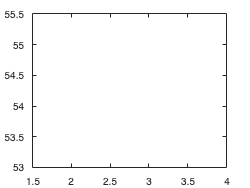

hold off

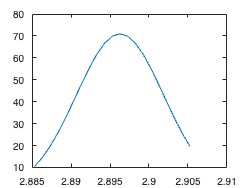

plot(x,y)